## SIMULAZIONE SISTEMA DI COMUNICAZIONE

## TX

T = 1;
t = (0:1e-3:T);
x = exp(2*pi*1i*t)

x =    1.0000 + 0.0000i   1.0000 + 0.0063i   0.9999 + 0.0126i   0.9998 + 0.0188i   0.9997 + 0.0251i   0.9995 + 0.0314i   0.9993 + 0.0377i   0.9990 + 0.0440i   0.9987 + 0.0502i   0.9984 + 0.0565i   0.9980 + 0.0628i   0.9976 + 0.0691i   0.9972 + 0.0753i   0.9967 + 0.0816i   0.9961 + 0.0879i   0.9956 + 0.0941i   0.9950 + 0.1004i   0.9943 + 0.1066i   0.9936 + 0.1129i   0.9929 + 0.1191i   0.9921 + 0.1253i   0.9913 + 0.1316i   0.9905 + 0.1378i   0.9896 + 0.1440i   0.9887 + 0.1502i   0.9877 + 0.1564i   0.9867 + 0.1626i   0.9856 + 0.1688i   0.9846 + 0.1750i   0.9834 + 0.1812i   0.9823 + 0.1874i   0.9811 + 0.1935i   0.9799 + 0.1997i   0.9786 + 0.2059i   0.9773 + 0.2120i   0.9759 + 0.2181i   0.9745 + 0.2243i   0.9731 + 0.2304i   0.9716 + 0.2365i   0.9701 + 0.2426i   0.9686 + 0.2487i   0.9670 + 0.2548i   0.9654 + 0.2608i   0.9637 + 0.2669i   0.9620 + 0.2730i   0.9603 + 0.2790i   0.9585 + 0.2850i   0.9567 + 0.2910i   0.9549 + 0.2970i   0.9530 + 0.3030i


figure(1);
subplot(2,1,1)
plot(t, real(x), 'r');
xlabel('Seconds');
subplot(2,1,2);
plot(t, imag(x), 'g');
xlabel('Seconds');
pause();

Campionamento

fs = 100;
N = T/1e-3;
M = N/fs;
xsample = x(1:M:N);
tSample = t(1:M:N);
subplot(2,1,1);
hold on 
stem(tSample,real(xsample), 'b');
hold off
subplot(2,1,2);
hold on 
stem(tSample,imag(xsample), 'b');
hold off

Quantizzatore uniforme

considero solo la parte reale d'ora in poi

% Parametri del quantizzatore
N_bit = 2;  % Numero di bit per quantizzazione
xmin = min(real(xsample));  % Valore minimo del segnale
xmax = max(real(xsample));  % Valore massimo del segnale

% Calcola i livelli di quantizzazione
numLevels = 2^N_bit;
delta = (xmax - xmin) / numLevels;  % Ampiezza di ogni livello
quantized_levels = xmin + delta * (0.5 + (0:numLevels-1))  % Livelli centrati

quantized_levels =    -0.7500   -0.2500    0.2500    0.7500



% Quantizzazione
quantized_indices = round((real(xsample) - xmin) / delta)  % Indici dei livelli

quantized_indices =      4     4     4     4     4     4     4     4     4     4     4     4     3     3     3     3     3     3     3     3     3     2     2     2     2     2     2     2     2     2     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0


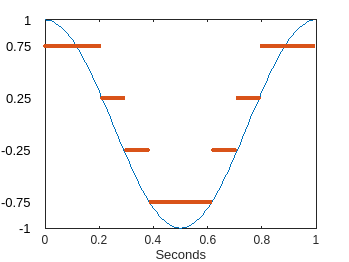

quantized_indices = min(max(quantized_indices, 0), numLevels - 1);  % Assicurati che gli indici siano validi
quantized_signal = quantized_levels(quantized_indices + 1);  % Converti in valori quantizzati (aggiungi 1 per l'indice)

figure(3);
plot(tSample, real(xsample),tSample,quantized_signal,'.');
xlabel('Seconds');
for i = 1:numLevels
    % Posiziona le etichette delle soglie
    text(-0.05, quantized_levels(i), num2str(quantized_levels(i)), 'VerticalAlignment', 'middle', 'HorizontalAlignment', 'right');
end

% Mostra anche le soglie estreme
text(-0.05, xmin, num2str(xmin), 'VerticalAlignment', 'middle', 'HorizontalAlignment', 'right');
text(-0.05, xmax, num2str(xmax), 'VerticalAlignment', 'middle', 'HorizontalAlignment', 'right');
yticks([]);

Quantizzazione della parte immaginaria tramite lloyd's algorithm e quantiz.

L'algoritmo di Lloyd funziona iterativamente: si inizia con un set iniziale di centroidi, e in ogni iterazione i dati del training set vengono assegnati al centroide più vicino. Successivamente, ogni centroide viene aggiornato per rappresentare la media dei punti assegnati, minimizzando così l'errore di quantizzazione (distorsione). Il processo continua fino a che non si raggiunge la convergenza, ovvero quando le posizioni dei centroidi non cambiano più significativamente.

len = 4; %numero di livelli
training_set = sin(2*tSample*pi); %serve ad allenare l'algoritmo per la convergenza
% dei centroidi
[partition,codebook] = lloyds(training_set,len); %restituisce i valori di quantizzazione ottimali (codebook)
% la partition contiene le soglie di quantizzazione
[index,quants] = quantiz(imag(xsample),partition,codebook);
plot(tSample, imag(xsample), tSample, quants, '.');
pause();
close all;

Codifica di Huffman  (parte immaginaria)

Calcolo a posteriori delle probabilità di simbolo

% Passo 1: Identifica i simboli unici
symbols = unique(quants);

% Passo 2: Conta la frequenza di ciascun simbolo
freqs = histcounts(quants, [symbols, max(symbols)+1]); % Frequenze dei simboli

% Passo 3: Calcola le probabilità dei simboli
probabilities = freqs / length(quants);

% Visualizza i risultati
disp('Simboli unici:'); disp(symbols);

Simboli unici:
   -0.8494   -0.3050    0.2745    0.8494



disp('Probabilità dei simboli:'); disp(probabilities);

Probabilità dei simboli:
    0.3100    0.1800    0.2000    0.3100



Codifica di Huffman

[dict, avglen] = huffmandict(symbols, probabilities); % Crea il dizionario di Huffman
data = quants; % Dati da codificare
encodedData = huffmanenco(data, dict); % Codifica Huffman
disp(encodedData) %Bisogna considerare coppie di bit

     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1    

disp(dict)

    {[-0.8494]}    {[0 1]}
    {[-0.3050]}    {[1 1]}
    {[ 0.2745]}    {[1 0]}
    {[ 0.8494]}    {[0 0]}



Codifica di Huffman  (parte reale)

Calcolo a posteriori delle probabilità di simbolo

% Passo 1: Identifica i simboli unici
symbols = unique(quantized_signal);

% Passo 2: Conta la frequenza di ciascun simbolo
freqs = histcounts(quantized_signal, [symbols, max(symbols)+1]); % Frequenze dei simboli

% Passo 3: Calcola le probabilità dei simboli
probabilities = freqs / length(quantized_signal);

% Visualizza i risultati
disp('Simboli unici:'); disp(symbols);

Simboli unici:
   -0.7500   -0.2500    0.2500    0.7500



disp('Probabilità dei simboli:'); disp(probabilities);

Probabilità dei simboli:
    0.2300    0.1800    0.1800    0.4100



Codifica di Huffman

[dict, avglen] = huffmandict(symbols, probabilities); % Crea il dizionario di Huffman
data = quantized_signal; % Dati da codificare
encodedData = huffmanenco(data, dict); % Codifica Huffman
disp(encodedData)

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

disp(dict) %Ad ogni simbolo è stata assegnata una lunghezza differente sulla base della sua probabilità

    {[-0.7500]}    {[  0 1]}
    {[-0.2500]}    {[0 0 1]}
    {[ 0.2500]}    {[0 0 0]}
    {[ 0.7500]}    {[    1]}



disp(avglen) %lunghezza media dei codici

    1.9500

